When designing a structure subject to dynamic loads (like earthquakes or wind), a significant issue is estimating its natural period(s) of vibration, which mainly depend on its mass and stiffness.

The 1st fundamental mode of vibration indicates the acceleration demand, and thus, the force demand on a structure. An effective way to avoid damage from earthquakes is to reduce its natural period.

The number of storeys indicates the number of modes of vibration the structure will be excited in. Higher modes require more energy, which is why the first 2 to 5 modes are most critical.

In a two-storey structure, there are two degrees of freedom which are described by a set of coupled, 2nd-order differential equations (see below). The “Lollipop Model” of a building lumps the stiffness and masses of each floor and connects them with springs.

This project simulates a two-storey building's behaviour when an externally applied force is not present (i.e., under free vibration). Viscous damping forces are also ignored.

(m1)(x1'') = (-k1)(x1) + (-k2)(x1 - x2)

(m2)(x2'') = (-k2)(x2 - x1)

Building parameters:

k1 = 4.66  % kN/mm

k1 = 4.6600

k2 = 4.66  % kN/mm

k2 = 4.6600

m1 = 0.0917  % (kN*s^2)/mm

m1 = 0.0917

m2 = 0.0765  % (kN*s^2)/mm

m2 = 0.0765


% init conditions:
% x1(0) = 100mm
% x2(0) = 50mm

% simulation time: 10s
% timestep: 0.018s

%% now run building_model.slx

Fourier Analysis to identify resonant frequncies:

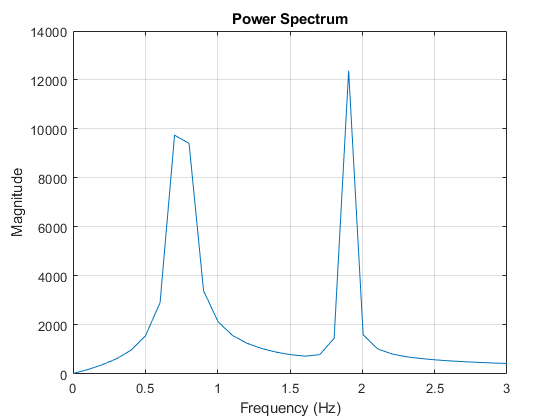

T = out.x1_data.time(end);  % simulation time
N = size(out.x1_data.signals.values, 1);  % number of points
t = N/T;  % 1/timestep

yfft = abs(fft(out.x1_data.signals.values));  % Fast Fourier Transform
t_list = linspace(0, t, N);

% plotting
plot(t_list, yfft);
xlim([0 3]);
title('Power Spectrum');
xlabel("Frequency (Hz)");
ylabel("Magnitude");
grid on;

By inspection using the *Data Tips*, the resonant frequencies are ~0.7 Hz and ~1.9 Hz. Exporting the data to *Microsoft Excel* reveals the resonant frequencies to be ~0.759549 Hz and ~1.884618 Hz.